# **Problema 1**

a) Implementați metoda lui Newton pentru rădăcini multiple.

Metoda lui Newton pentru **radacini simple **are rata de convergenta cel putin patratica, insa pentru radacini multiple, aceeasi metoda are rata de convergenta liniara.

Pentru a imbunatati rata de convergenta, putem folosi urmatoarea relatie de recurenta:


$$x_{k+1} =x_k -m\cdot \frac{f\left(x_k \right)}{f^{\prime } \left(x_k \right)},m=\mathrm{ordin}\;\mathrm{de}\;\mathrm{multiplicitate}$$


Cu rata de convergenta: $\frac{m-1}{m}$

Daca insa m este necunoscut, il putem aproxima prin:


$$m\approx \frac{\ln |\frac{f\left(x_{k-1} \right)}{f\left(x_{k-2} \right)}|}{\ln |\frac{x_{k-1} -x_k }{x_{k-2} -x_k }|}$$


b) Se consideră ecuația $e^{-x^2 } =\cos \left(x\right)+1$, pe [0, 4]. Ce se întâmplă dacă se aplică metoda lui Newton cu x0 = 0 si x0 = 1?

Pentru $x_0 =0:f\left(x_0 \right)=-1,f^{\prime } \left(x_0 \right)=0$. Derivata se anulează în 0, astfel prima iterație va tinde la infinit.

Pentru $\begin{array}{l}
x_0 =1:\\
f\left(x_0 \right)=\frac{1}{e}-\cos \left(1\right)-1\approx -1\ldotp 172422\\
f^{\prime } \left(x_0 \right)=-\frac{2}{e}+\sin \left(1\right)\approx 0\ldotp 105712
\end{array}$

c)  Remarcați convergența lentă, explicați fenomenul și găsiți un remediu.

Insa daca nu cunoastem ordinul de multiplicitate, convergenta este foarte lenta. Am putea empiric sa incercam sa ghicim ordinul de multiplicitate, astfel ajungand la o solutie. Din grafic se observa ca avem 2 radacini pe [0, 4]. Pentru m != 2, de ex. 1 sau 3, se poate observa ca metoda lui Newton converge intr-un numar mai mare de iteratii, 23 si 26, in timp ce pentru m = 2 metoda converge in 6 iteratii. Pentru m > 3, metoda pare sa nu mai convearga.

d) Când este mai mic numărul de iterații: când se cunoaște multiplicitatea sau se estimează?

Numărul de iterații este mai mic atunci când se cunoaste multiplicitatea.

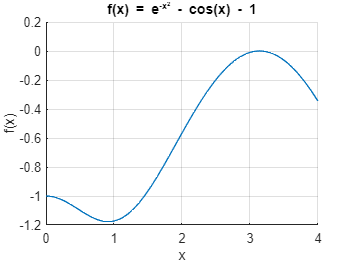

f = @(x) exp(-x.^2) - cos(x) - 1;
df = @(x) -2 .* x .* exp(-x.^2) + sin(x);

figure; hold on;
fplot(f, [0, 4])
title('f(x) = e^{-x^2} - cos(x) - 1');
grid on;
xlabel('x');
ylabel('f(x)');

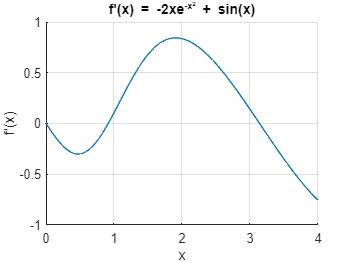


figure; hold on;
fplot(df, [0, 4]);
title("f'(x) = -2xe^{-x^2} + sin(x)")
grid on;
xlabel('x');
ylabel("f'(x)")

[root0, iter0] = newton_multiple_roots(f, df, 0);

fprintf("[x0 = 0] Root: %.16e | Iterations: %d\n", root0, iter0);

[x0 = 0] Root: NaN | Iterations: 9999


[root1, iter1] = newton_multiple_roots(f, df, 1);
fprintf("[x0 = 1] Root: %.16e | Iterations: %d\n", root1, iter1);

[x0 = 1] Root: -7.0148622361771078e+04 | Iterations: 8670


# **Problema 2**

Deduceți o formulă de cuadratură de forma


$$\int_{-1}^1 \frac{f\left(t\right)}{\sqrt{1-t^2 }}\textrm{dt}=A_0 f\left(-1\right)+A_1 f\left(t_1 \right)+A_2 f\left(t_2 \right)+A_3 f\left(t_3 \right)+A_4 f\left(1\right)+R_f$$


care să aibă grad maxim de exactitate.

Intervalul și ponderea se potrivesc cu valorile pentru polinoamele ortogonale Cebîșev#1.

syms t k integer
assumeAlso(k >= 0)

f = t^k / sqrt(1 - t^2);
intf = int(f, t, -1, 1);
disp(intf);

$$\frac{\left({\left(-1\right)}^{k}+1\right)\,\beta (\frac{1}{2},\frac{k}{2}+\frac{1}{2})}{2}$$

for i = 0:7
    I = vpa(subs(intf, k, i), 6);
    fprintf("k = %2d | I = %.6e\n", i, I);
end

k =  0 | I = 3.141593e+00
k =  1 | I = 0.000000e+00
k =  2 | I = 1.570796e+00
k =  3 | I = 0.000000e+00
k =  4 | I = 1.178097e+00
k =  5 | I = 0.000000e+00
k =  6 | I = 9.817477e-01
k =  7 | I = 0.000000e+00



$$\int_{-1}^1 \frac{t^k }{\sqrt{1-t^2 }}\mathrm{dt}=\frac{\left({\left(-1\right)}^k +1\right)\cdot \beta \left(\frac{1}{2},\frac{k}{2}+\frac{1}{2}\right)}{2},\mathrm{unde}\;\beta \left(n,m\right)-\mathrm{functia}\;\mathrm{Beta}-\mathrm{Euler}$$



$$\left\lbrack \begin{array}{ccccccc}
f\left(t\right) & f\left(-1\right) & f\left(t_1 \right) & f\left(t_2 \right) & f\left(t_3 \right) & f\left(1\right) & \int_{-1}^1 \frac{f\left(t\right)}{\sqrt{1-t^2 }}\mathrm{dt}\\
1 & 1 & 1 & 1 & 1 & 1 & 3\ldotp 14159\\
t & -1 & t_1  & t_2  & t_3  & 1 & 0\\
t^2  & 1 & t_1^2  & t_2^2  & t_3^2  & 1 & 1\ldotp 570796\\
t^3  & -1 & t_1^3  & t_2^3  & t_3^3  & 1 & 0\\
t^4  & 1 & t_1^4  & t_2^4  & t_3^4  & 1 & 1\ldotp 178097\\
t^5  & -1 & t_1^5  & t_2^5  & t_3^5  & 1 & 0\\
t^6  & 1 & t_1^6  & t_2^6  & t_3^6  & 1 & 0\ldotp 987747\\
t^7  & -1 & t_1^7  & t_2^7  & t_3^7  & 1 & 0
\end{array}\right\rbrack$$


Rezulta urmatorul sistem:


$$\begin{array}{l}
f\left(t\right)=1:A_0 +A_1 +A_2 +A_3 +A_4 =3\ldotp 14159\\
f\left(t\right)=t:-A_0 +t_1 A_1 +t_2 A_2 +t_3 A_3 +A_4 =0\\
f\left(t\right)=t^2 :A_0 +t_1^2 A_1 +t_2^2 A_2 +t_3^2 A_3 +A_4 =1\ldotp 570796\\
f\left(t\right)=t^3 :-A_0 +t_1^3 A_1 +t_2^3 A_2 +t_3^3 A_3 +A_4 =0\\
f\left(t\right)=t^4 :A_0 +t_1^4 A_1 +t_2^4 A_2 +t_3^4 A_3 +A_4 =1\ldotp 178097\\
f\left(t\right)=t^5 :-A_0 +t_1^5 A_1 +t_2^5 A_2 +t_3^5 A_3 +A_4 =0\\
f\left(t\right)=t^6 :A_0 +t_1^6 A_1 +t_2^6 A_2 +t_3^6 A_3 +A_4 =0\ldotp 987747\\
f\left(t\right)=t^7 :-A_0 +t_1^7 A_1 +t_2^7 A_2 +t_3^7 A_3 +A_4 =0
\end{array}$$


Rezolvam cu MATLAB Symbolic.

syms A0 A1 A2 A3 A4 t1 t2 t3

eq1 = A0 + A1 + A2 + A3 + A4 == 3.14159;
eq2 = -A0 + t1 * A1 + t2 * A2 + t3 * A3 + A4 == 0;
eq3 = A0 + t1^2 * A1 + t2^2 * A2 + t3^2 * A3 + A4 == 1.570796;
eq4 = -A0 + t1^3 * A1 + t2^3 * A2 + t3^3 * A3 + A4 == 0;
eq5 = A0 + t1^4 * A1 + t2^4 * A2 + t3^4 * A3 + A4 == 1.178097;
eq6 = -A0 + t1^5 * A1 + t2^5 * A2 + t3^5 * A3 + A4 == 0;
eq7 = A0 + t1^6 * A1 + t2^6 * A2 + t3^6 * A3 + A4 == 0.987747;
eq8 = -A0 + t1^7 * A1 + t2^7 * A2 + t3^7 * A3 + A4 == 0;

solution = solve([eq1, eq2, eq3, eq4, eq5, eq6, eq7, eq8], [A0, A1, A2, A3, A4, t1, t2, t3]);
fields = fieldnames(solution);
for i = 1:length(fields)
    fprintf('%s = ', fields{i});
    disp(vpa(solution.(fields{i}), 6));
    fprintf('\n');
end

A0 = 

$$\left(\begin{array}{c} 0.404342\\ 0.404342\\ 0.404342\\ 0.404342\\ 0.404342\\ 0.404342 \end{array}\right)$$

A1 = 

$$\left(\begin{array}{c} 0.786132\\ 0.786132\\ 0.786132\\ 0.786132\\ 0.760642\\ 0.760642 \end{array}\right)$$

A2 = 

$$\left(\begin{array}{c} 0.786132\\ 0.786132\\ 0.760642\\ 0.760642\\ 0.786132\\ 0.786132 \end{array}\right)$$

A3 = 

$$\left(\begin{array}{c} 0.760642\\ 0.760642\\ 0.786132\\ 0.786132\\ 0.786132\\ 0.786132 \end{array}\right)$$

A4 = 

$$\left(\begin{array}{c} 0.404342\\ 0.404342\\ 0.404342\\ 0.404342\\ 0.404342\\ 0.404342 \end{array}\right)$$

t1 = 

$$\left(\begin{array}{c} 0.69622\\ -0.69622\\ 0.69622\\ -0.69622\\ 0\\ 0 \end{array}\right)$$

t2 = 

$$\left(\begin{array}{c} -0.69622\\ 0.69622\\ 0\\ 0\\ 0.69622\\ -0.69622 \end{array}\right)$$

t3 = 

$$\left(\begin{array}{c} 0\\ 0\\ -0.69622\\ 0.69622\\ -0.69622\\ 0.69622 \end{array}\right)$$

Rezulta solutiile:


$$
A0 = \left(\begin{array}{c} 0.404342\\ 0.404342\\ 0.404342\\ 0.404342\\ 0.404342\\ 0.404342 \end{array}\right) \\
A1 = \left(\begin{array}{c} 0.786132\\ 0.786132\\ 0.786132\\ 0.786132\\ 0.760642\\ 0.760642 \end{array}\right) \\
A2 = \left(\begin{array}{c} 0.786132\\ 0.786132\\ 0.760642\\ 0.760642\\ 0.786132\\ 0.786132 \end{array}\right) \\
A3 = \left(\begin{array}{c} 0.760642\\ 0.760642\\ 0.786132\\ 0.786132\\ 0.786132\\ 0.786132 \end{array}\right) \\
A4 = \left(\begin{array}{c} 0.404342\\ 0.404342\\ 0.404342\\ 0.404342\\ 0.404342\\ 0.404342 \end{array}\right) \\
t1 = \left(\begin{array}{c} 0.69622\\ -0.69622\\ 0.69622\\ -0.69622\\ 0\\ 0 \end{array}\right) \\
t2 = \left(\begin{array}{c} -0.69622\\ 0.69622\\ 0\\ 0\\ 0.69622\\ -0.69622 \end{array}\right) \\
t3 = \left(\begin{array}{c} 0\\ 0\\ -0.69622\\ 0.69622\\ -0.69622\\ 0.69622 \end{array}\right)$$


Alegem prima solutie, adica:


$$\int_{-1}^1 \frac{f\left(t\right)}{\sqrt{1-t^2 }}\mathrm{dt}=\;0\ldotp 404342+0\ldotp 786132\cdot f\left(0\ldotp 69622\right)+0\ldotp 786132\cdot f\left(-0\ldotp 69622\right)+0\ldotp 760642\cdot f\left(0\right)+0\ldotp 40434+R\left(f\right)$$



$$\begin{array}{l}
R\left(f\right)=\frac{f^{\left(8\right)} \left(\xi \right)}{8!}\cdot \int_{-1}^1 \frac{\omega \left(t\right)}{\sqrt{1-t^2 }}\mathrm{dt},\mathrm{unde}\;\omega \left(t\right)=\left(t+1\right)\left(t-t_1 \right)\left(t-t_2 \right)\left(t-t_3 \right)\left(t-1\right),\xi \in \left(-1,1\right)\\
\int_{-1}^1 \frac{\omega \left(t\right)}{\sqrt{1-t^2 }}\mathrm{dt}=\frac{\pi \left(t_1 +t_2 +t_3 +4t_1 t_2 t_3 \right)}{8},\mathrm{iar}\;\mathrm{cu}\;\mathrm{valorile}\;\mathrm{aproximate}\Rightarrow \omega \left(t\right)=0\Rightarrow R\left(f\right)=0
\end{array}$$


syms t t1 t2 t3

omega = (t+1)*(t-t1)*(t-t2)*(t-t3)*(t-1) / sqrt(1 - t^2);
int_omega = int(omega, t, -1, 1);
fprintf("I_omega = ");

I_omega = 

disp(int_omega);

$$\frac{\pi \,\left(t_{1}+t_{2}+t_{3}+4\,t_{1}\,t_{2}\,t_{3}\right)}{8}$$

fprintf("\n");

omega_known = (t+1)*(t-0.69622)*(t+0.69622)*(t-0)*(t-1) / sqrt(1 - t^2);
int_omega_known = int(omega_known, t, -1, 1);
fprintf("I_omega = ");

I_omega = 

disp(vpa(int_omega_known, 6));

$$0.0$$

fprintf("\n");

Rezulta formula de cuadratura:


$$\int_{-1}^1 \frac{f\left(t\right)}{\sqrt{1-t^2 }}\mathrm{dt}=\;0\ldotp 404342+0\ldotp 786132\cdot f\left(0\ldotp 69622\right)+0\ldotp 786132\cdot f\left(-0\ldotp 69622\right)+0\ldotp 760642\cdot f\left(0\right)+0\ldotp 404342$$


# **Problema 3**

Șirul $\epsilon_n =e^{-e^n }$ converge către 0 când $n\to \infty$. Cât este ordinul de convergență?

Pentru o metoda iterativa care converge la o valoare $L$, un sir $\left(x_k \right)$ are ordinul de convergenta $q\ge 1$ si rata de convergenta $\mu$ daca:


$$\lim_{k\to \infty } \frac{|x_{k+1} -L|}{|x_k -L|^q }=\mu$$


Sirul nostru $\epsilon_n =e^{-e^n }$ are ordinul de convergenta $q$ daca $\exists \;C>0$ a.i.:


$$\begin{array}{l}
\epsilon_{n+1} \approx C\cdot \epsilon_n^q \\
\epsilon_{n+1} ={e^{-e} }^{n+1} =e^{-e\cdot e^n } ={\left(e^{-e^n } \right)}^e =\epsilon_n^e \\
\Rightarrow \epsilon_{n+1} =1\cdot \epsilon_n^e \Rightarrow q=e
\end{array}$$


Rezulta astfel ca ordinul de convergenta este constanta lui Euler.

function [root, iter] = newton_multiple_roots(f, df, x0, m, tol, max_iter)
    %% NEWTOK_MULTIPLE_ROOTS - Newton-Raphson method adapted for multiple roots
    %
    %  Inputs:
    %
    %  f        - function to approximate;
    %  df       - first derivative of the function to approximate;
    %  x0       - initial guess;
    %  tol      - acceptable error between iterations;
    %  max_iter - maximum number of iterations
    %
    %  Outputs
    %
    %  root     - the approximated root;
    %  iter     - the number of iterations took to approximate the root;
    %
    %  Error: if the number of iterations is exceeded.
    known_m = true;

    if nargin < 3
        x0 = 0;
    end
    if nargin < 4
        known_m = false;
    end
    if nargin < 5
        tol = 1e-6;
    end
    if nargin < 6
        max_iter = 10000;
    end

    % Keeping track of 3 iterations: x_{k-2}, x_{k-1}, x_k
    x = zeros(1, max_iter + 2);
    fx = zeros(1, max_iter + 2);
    x(1) = x0;
    fx(1) = f(x0);

    % First step, with classic Newton-Raphson
    x(2) = x(1) - fx(1) / df(x(1));
    fx(2) = f(x(2));

    % Second step, again with classic Newton-Raphson
    x(3) = x(2) - fx(2) / df(x(2));
    fx(3) = f(x(3));

    for i = 4:max_iter+1
        % Estimating the multiplicity of the roots, if it is not known
        if ~known_m 
            num = log(abs(fx(i-1) / fx(i-2)));
            den = log(abs((x(i-1) - x(i-2)) / (x(i-2) - x(i-3))));
            if isnan(num) || isnan(den) || isinf(num) || isinf(den) || den == 0
                m = 1;
            else
                m = num / den;
            end
        end

        % Computing the iteration
        x(i) = x(i - 1) - m * fx(i-1) / df(x(i-1));
        fx(i) = f(x(i));

        % Checking if the approximation is acceptable
        if abs(x(i) - x(i-1)) < tol
            root = x(i);
            iter = i - 1;
            return;
        end
    end

    root = x(max_iter - 1);
    iter = max_iter - 1;
    warning('Approximation did not converge in %d maximum iterations', max_iter);
end